
x = 1.5;
y = 3;
g = @(x) x.^2;
f = @(x) (x-1).^2+(x.^2-3).^2;
df = derivate(f);
ddf = derivate(df);
xx = linspace(0.5,x+0.5,100)

xx =    0.500000000000000   0.515151515151515   0.530303030303030   0.545454545454545   0.560606060606061   0.575757575757576   0.590909090909091   0.606060606060606   0.621212121212121   0.636363636363636   0.651515151515151   0.666666666666667   0.681818181818182   0.696969696969697   0.712121212121212   0.727272727272727   0.742424242424242   0.757575757575758   0.772727272727273   0.787878787878788   0.803030303030303   0.818181818181818   0.833333333333333   0.848484848484849   0.863636363636364   0.878787878787879   0.893939393939394   0.909090909090909   0.924242424242424   0.939393939393939   0.954545454545455   0.969696969696970   0.984848484848485   1.000000000000000   1.015151515151515   1.030303030303030   1.045454545454545   1.060606060606061   1.075757575757576   1.090909090909091   1.106060606060606   1.121212121212121   1.136363636363636   1.151515151515151   1.166666666666667   1.181818181818182   1.196969696969697   1.212121212121212   1.227272727272727   1.2424242424

plot(xx,f(xx))
axis equal
hold on
for i=1:10
    plot(x,f(x),"r*")
    x=x-df(x)/ddf(x)
end

x =    1.705882352941176


x =    1.673865102830913


x =    1.672982311413784


x =    1.672981647855317


x =    1.672981647854942


x =    1.672981647854942


x =    1.672981647854942


x =    1.672981647854942


x =    1.672981647854942


x =    1.672981647854942


x2 = secant(1,f,1.5)

x2 =    2.231206034011894


x3 = regula_falsi(1.2,1.6,f)

x3 =    1.600824789673047


r = sqrt(f(x))

r =    0.702394862644220


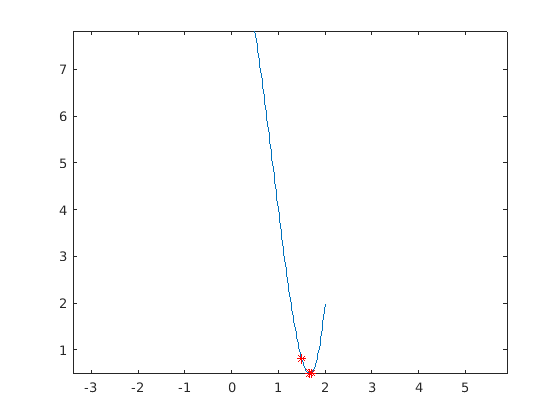

hold off

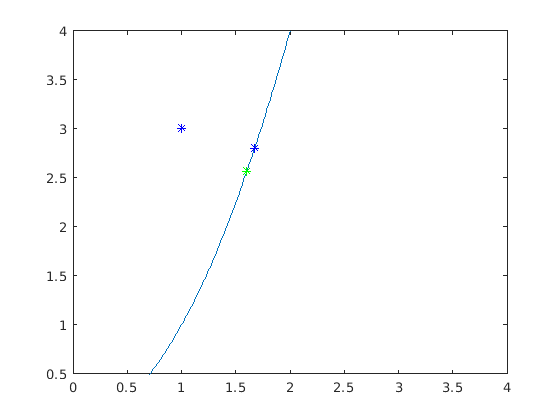

plot(xx,g(xx))
xlim([0 4])
ylim([0.5 4])
hold on
plot([x,1],[g(x),3],"b*")
plot(x2,g(x2),"r*")
plot(x3,g(x3),"g*")
hold off

f(x+r)

ans =    8.874010002749346


%Second task
f = @(x) abs(exp(1).^x-x.^2) + x;
xx = linspace(-2,2,100)

xx =   -2.000000000000000  -1.959595959595960  -1.919191919191919  -1.878787878787879  -1.838383838383838  -1.797979797979798  -1.757575757575758  -1.717171717171717  -1.676767676767677  -1.636363636363636  -1.595959595959596  -1.555555555555556  -1.515151515151515  -1.474747474747475  -1.434343434343434  -1.393939393939394  -1.353535353535354  -1.313131313131313  -1.272727272727273  -1.232323232323232  -1.191919191919192  -1.151515151515152  -1.111111111111111  -1.070707070707071  -1.030303030303030  -0.989898989898990  -0.949494949494950  -0.909090909090909  -0.868686868686869  -0.828282828282828  -0.787878787878788  -0.747474747474748  -0.707070707070707  -0.666666666666667  -0.626262626262626  -0.585858585858586  -0.545454545454545  -0.505050505050505  -0.464646464646465  -0.424242424242424  -0.383838383838384  -0.343434343434343  -0.303030303030303  -0.262626262626263  -0.222222222222222  -0.181818181818182  -0.141414141414141  -0.101010101010101  -0.060606060606061  -0.0202020202

plot(xx,f(xx),xx,zeros(length(xx)))
hold on
x_sec = secant(-1,f,0)

x_sec =   -0.444128958770872


x_reg = regula_falsi(-1.5,-0.5,f)

x_reg =   -1.235346233464687


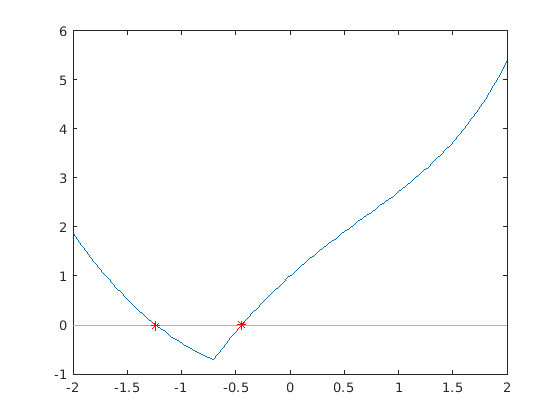

plot([x_sec,x_reg],[f(x_sec),f(x_reg)],"r*")

function [x3] = secant(x1, f, x2)
f1 = f(x1);
f2 = f(x2);
it = 0;
maxit = 30;
precision = 0.001;
    while abs(x2 - x1) > precision && maxit > it
        %plot([x1,x2],[f1,f2],"g--*")
        it = it + 1;
        x3 = x2 - f2*(x2-x1)/(f2-f1);
        x1 = x2;
        f1 = f2;
        x2 = x3;
        f2 = f(x3);
    end
end

function [x] = regula_falsi(a, b, f)
    precision = 0.001;
    it = 0;
    maxit = 30;
    while abs(a - b) > precision && maxit > it
       it = it + 1;
       x = b - (f(b)*((b - a)/(f(b) - f(a))));
       if x == a || x == b
           break
       end
       if f(x) * f(a) >= 0
           a = x;
       else
           b = x;
       end
    end
end